Open image

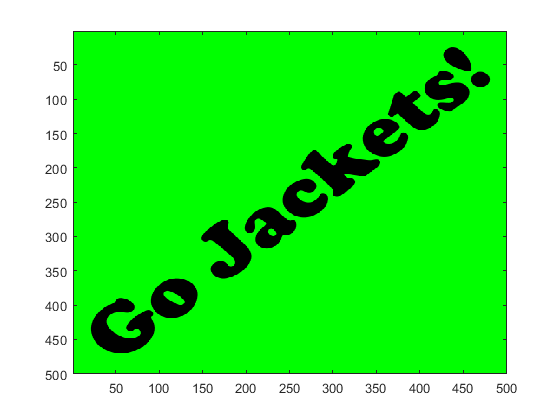

text = imread('goJackets.png');
% imshow(text)
image(text);

Create image mask

%2D mask
mask2d = (text(:,:,1)<128) & (text(:,:,2)>128) & (text(:,:,3)<128);

%3D mask
mask3d(:,:,1) =  mask2d;
mask3d(:,:,2) =  mask2d;
mask3d(:,:,3) =  mask2d;
%or
mask3d = cat(3,mask2d, mask2d, mask2d);

Use 3D mask to assign a background color from a color patch of the same size

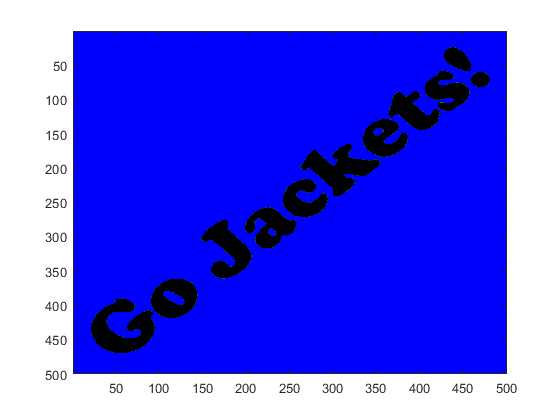

%Get size of image - eventhough l will always be 3, if you do not indicate
%a thrid output, the second output will be c*l.
[r,c,l] = size(text);

%Create a color patch the same size of the image
blue(1:r,1:c,1) = uint8(0);
blue(1:r,1:c,2) = uint8(0);
blue(1:r,1:c,3) = uint8(255);

%Use 3D mask on image and color patch to change the desired pixels
newtext = text; %I copied the original so that it remains unchanged for the examples that follow
newtext(mask3d) = blue(mask3d); %Corresponing "trues" in the mask get changed to the color of the patch

%Show the image
image(newtext)

Use 3D mask to assign a text color from a color patch of the same size

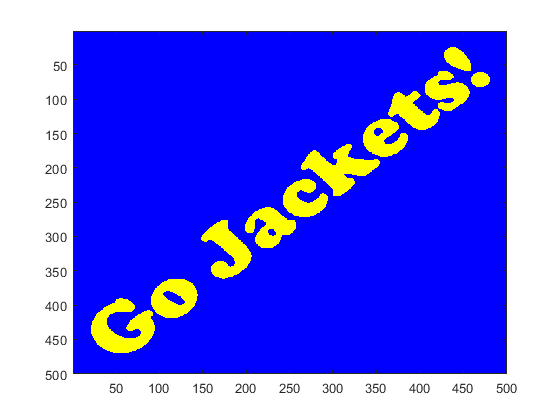

%Get the size of the image
[r,c,l] = size(text);

%Create a color patch the same size of the image
yellow(1:r,1:c,1) = uint8(255);
yellow(1:r,1:c,2) = uint8(255);
yellow(1:r,1:c,3) = uint8(0);

%Since I want to change the text color of the image for which I just changed the
%background color, I perform inverse masking on the results of lines 15-27
newtext(~mask3d) = yellow(~mask3d);

%Show image
image(newtext)

Use another image of the same size to assign a new background

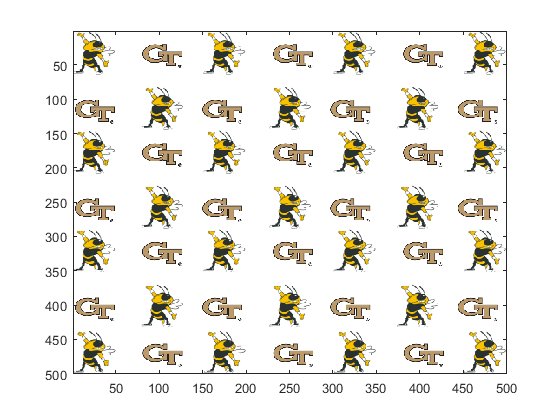

%Open background image
bkgnd = imread('goJacketsBackground.png');
image(bkgnd);

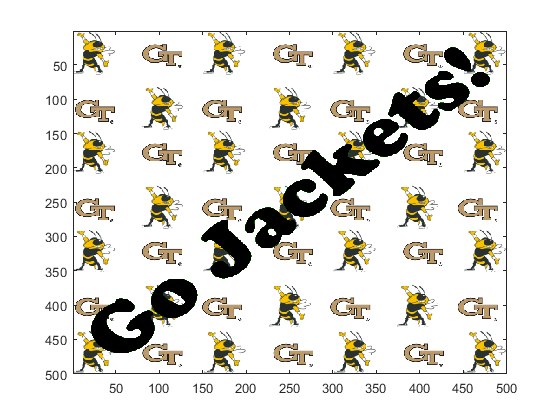


%Method 3 - Use 3D mask to index all layers at once
newImage = text; %Again, made a copy of the original

%Corresponing "trues" in the mask get changed to the color of the
%corresponding pixel in the background image
newImage(mask3d) = bkgnd(mask3d);

%Show image
image(newImage)

Use another image of the same size to assign a new pattern to the text

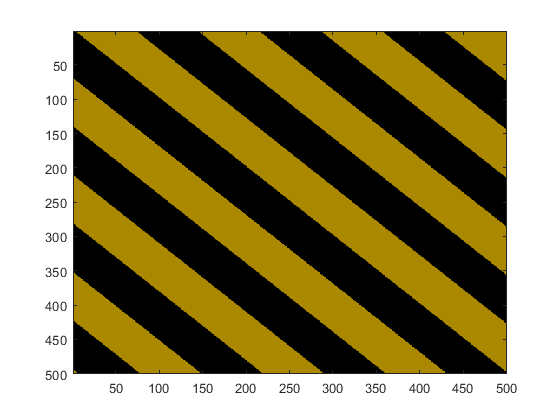

%Open background image
bkgnd = imread('stripes.png');
image(bkgnd);

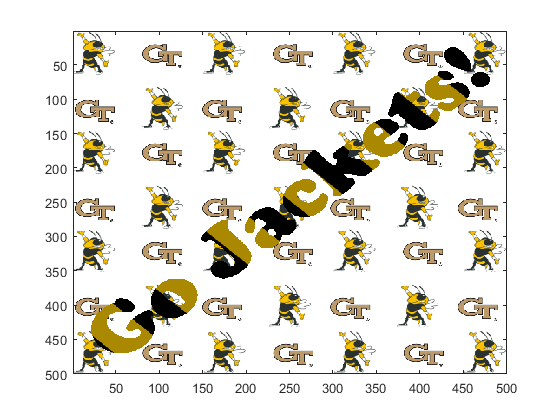


%Method 3 - Use 3D mask to index all layers at once

%Corresponing "trues" in the mask get changed to the color of the
%corresponding pixel in the background image
newImage(~mask3d) = bkgnd(~mask3d);

%Show image
image(newImage)